# Uniform sampling of E. coli core via Riemannian Hamiltonain Monte Carlo (RHMC)

## Author(s): Yunbum Kook (Georgia Tech), Yin Tat Lee (University of Washington), Ruoqi Shen (University of Washington), Santosh Vempala (Georgia Tech)

## Reviewer(s): 

## Introduction

The flux space $\Omega$ for a given set of biochemical and physiologic constraints is represented by: 


$$\Omega = \{v \mid Sv=b; l \leq v\leq u\}$$


where $v$ represents feasible flux vectors,  $S\in\mathcal{Z}^{m\times n}$ the stoichiometric matrix, while $l$ and $u$ are lower and upper bounds on fluxes. These criteria allow a wide range of admissible flux distributions which, in FBA are commonly further restricted by introducing an objective to optimize, transforming the question of admissible fluxes into an FBA problem${\;}^1$ of the form


$$\begin{array}{ll}
\min\limits _{v} & c^{T}v\\
\text{s.t.} & Sv=b,\\
 & l\leq v\leq u,
\end{array}$$


where $c$ is a linear objective function (e.g., biomass, ATP consumption, HEME production etc.). Even under these conditions there is commonly a range of optimal flux distributions, which can be investigated using flux variability analysis. If the general capabilities of the model are of interest, however, uniform sampling of the entire flux space $\Omega$ is able to provide an unbiased characterization, and therefore, can be used to investigate the biochemical networks. It requires collecting a statistically meaningful number of flux distributions uniformly spread throughout the whole flux space and then analysing their properties. There are three basic steps to perform a uniform sampling for a set of feasible fluxes:

- Define the flux space to be sampled from physical and biochemical constraints

- Randomly sample the defined flux space based on statistical criteria

- If necessary, section the flux space post-sampling.

In this tutorial, we introduce how to run a sampling method called the Riemannian Hamiltonian Monte Carlo (RHMC) for uniform or Gaussian sampling from the flux space. This algorithm first preprocesses the flux space and then performs sampling based on RHMC. For large models, it exhibits a significant speed-up in sampling time compared to the default sampling algorithm, coordinate hit-and-run with rounding (CHRR). First, the preprocessing part in RHMC is numerically more stable and finishes in one minute even for an instance with 100000 reactions, whereas the preprocessing basd on John's ellipsoid in the CHRR takes much longer (the time complexity is super-linear time in the dimension of instances). Next, the sampling procedure iteself in RHMC is substantially faster than the random walk based on coordinate hit-and-run in CHRR, since the random walk in RHMC mixes much faster than CHRR.

## Materials - Equipment Setup

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

Please note that some of the plotting options in the tutorial require Matlab 2016a or higher. Moreover, the tutorial requires a working installation of the Parallel Computing Toolbox.

% uncomment this line below to see what toolboxes are installed
% ver

## Load E. coli core model

The way to load a model into The COBRA Toolbox is to use the `readCbModel` function. 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
    modelOri = readCbModel(fileName);
end

Each model.subSystems{x} is a character array, and this format is retained.


%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;

### E. coli core in aerobic an anaerobic conditions

Remove the objective from the model and set a small lower bound on the rate of biomass reactions.

biomassRxnAbbr = 'Biomass_Ecoli_core_N(w/GAM)-Nmet2';
ibm = find(ismember(model.rxns, biomassRxnAbbr));  % column index of the biomass reaction
model.lb(ibm)=0.05;
model.c(:)=0;

We investigate ATP energy production with limited and unlimited oxygen uptake. 

aerobicModel = changeRxnBounds(model,'EX_o2(e)',-17,'l');
anAerobicModel = changeRxnBounds(model,'EX_o2(e)',-1,'l');

## Sampling

We walk you through how to run RHMC for sampling, taking a look at simple examples for (1) uniform samping and (2) Gaussian sampling. Then we go over a list of important parameters in RHMC.

### Uniform Sampling

RHMC can be called via the function `sampleCbModel`. The main inputs to `sampleCbModel` are a COBRA model structure, the name of the selected sampler, and a parameter struct that controls properties of the sampler used. In an instance of RHMC, for uniform sampling, the time limit for sampling (`maxTime)` and the desired number of samples (`nPointsReturned)` are the only parameters that need to be set, since other parameters for RHMC are automatically set to defafult values by the algorithm. Note that you can manually set these parameters and we illustrate below how to do it.

RHMC returns as many statistically (nearly) independent samples as requested. If the running time of RHMC reaches the time limit set by `maxTime`, then the program will terminate and return independent samples drawn before the time limit. 

options.nPointsReturned = 100;
options.maxTime = 3600; % 1hr

% Uniform Sampling
[~, X1_un] = sampleCbModel(aerobicModel, [], 'RHMC', options);

  Time spent |    Time left |                  Progress |   Est Samples |  AccProb | StepSize |  MixTime
00d:00:00:11 | 00d:00:00:00 | ######################### |   161 /   100 | 0.950994 | 0.200000 |     31.4
Done!


[~, X1_lim] = sampleCbModel(anAerobicModel, [], 'RHMC', options);

  Time spent |    Time left |                  Progress |   Est Samples |  AccProb | StepSize |  MixTime
00d:00:00:05 | 00d:00:00:00 | ######################### |   112 /   100 | 0.917996 | 0.181818 |     23.7
Done!


The sampler outputs the sampled flux distributions (X_un and X_lim). 

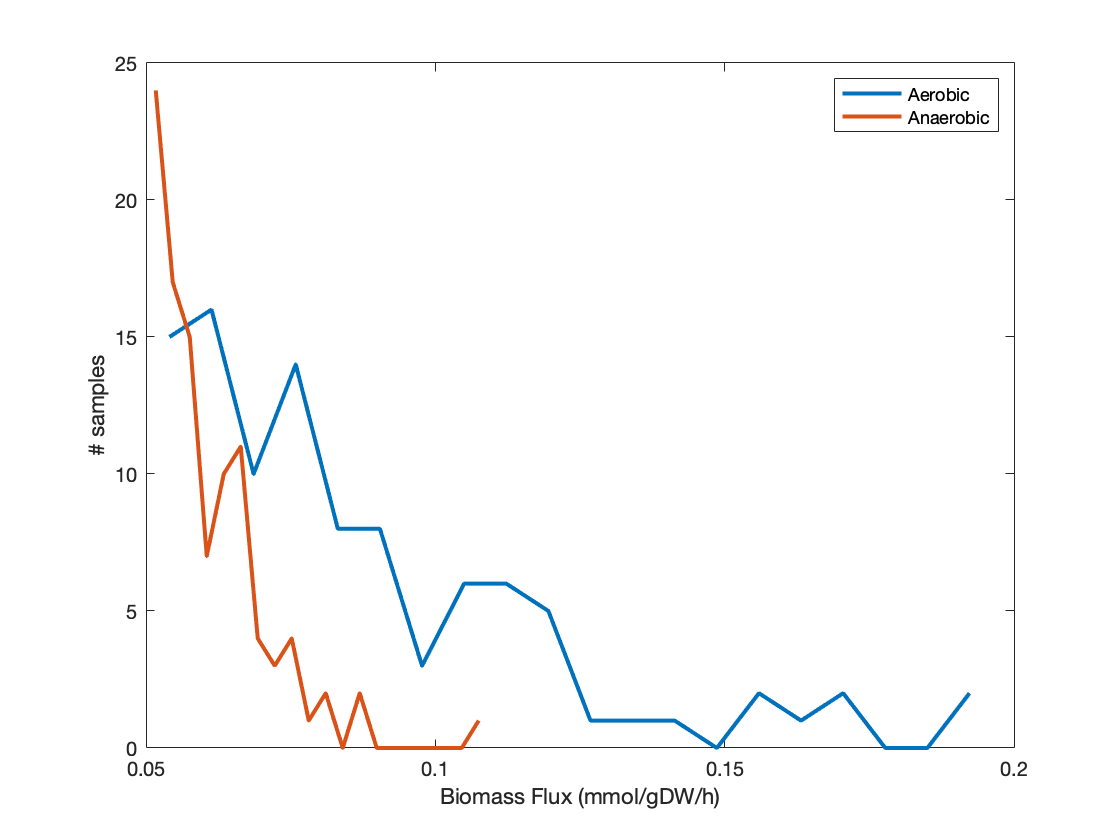

nbins = 20;
[yUn, xUn] = hist(X1_un(ibm, :), nbins,'linewidth', 2);
[yLims, xLims] = hist(X1_lim(ibm, :), nbins,'linewidth', 2);

figure;
plot(xUn, yUn, xLims, yLims,'linewidth', 2);
legend('Aerobic', 'Anaerobic')
xlabel('Biomass Flux (mmol/gDW/h)')
ylabel('# samples')

### Gaussian Sampling

To sample from the Gaussian distribution (restricted to the flux space) with mean `vMean` and diagonal covariance matrix `vCov `(i.e., a probability density proportional to $e^{-\frac{(x-\mu)^{T}\Sigma^{-1}(x-\mu)}{2}}$, where $\mu = vMean$ and $\Sigma = diag(vCov)$), provide these vectors as fields to the model struct.

% Gaussian Sampling
% * If you want to sample from the Standard Gaussian, you should provide the mean vector and the covariance vector used for a diagonal covariance matrix.

% Example for the standard Gaussian distribution
options.nPointsReturned = 100;
numVar = size(aerobicModel.S, 2);
aerobicModel.vMean = zeros(numVar, 1); 
aerobicModel.vCov = ones(numVar, 1);
[~, X2_un] = sampleCbModel(aerobicModel, [], 'RHMC', options);

  Time spent |    Time left |                  Progress |   Est Samples |  AccProb | StepSize |  MixTime
00d:00:00:07 | 00d:00:00:00 | ######################### |   105 /   100 | 0.957425 | 0.200000 |     23.1
Done!


[~, X2_lim] = sampleCbModel(anAerobicModel, [], 'RHMC', options); 

  Time spent |    Time left |                  Progress |   Est Samples |  AccProb | StepSize |  MixTime
00d:00:00:08 | 00d:00:00:00 | ######################### |   145 /   100 | 0.944246 | 0.199170 |     32.5
Done!


The sampler outputs the sampled flux distributions (X2_un and X2_lim). 

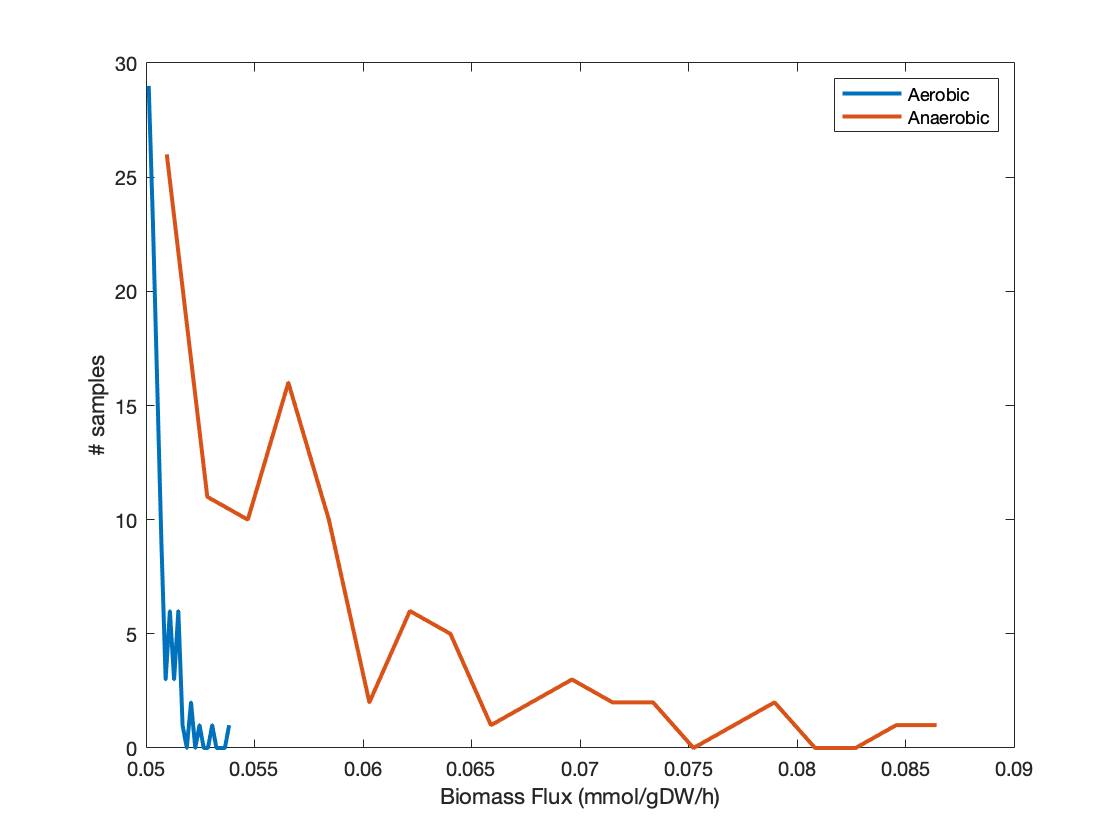

nbins = 20;
[yUn, xUn] = hist(X2_un(ibm, :), nbins,'linewidth', 2);
[yLims, xLims] = hist(X2_lim(ibm, :), nbins,'linewidth', 2);

figure;
plot(xUn, yUn, xLims, yLims,'linewidth', 2);
legend('Aerobic', 'Anaerobic')
xlabel('Biomass Flux (mmol/gDW/h)')
ylabel('# samples')

## Parameters

When running RHMC, the list of parameters and their default values can be found [here](https://github.com/ConstrainedSampler/PolytopeSamplerMatlab/blob/master/code/default_options.m). Let us discuss some important parameters.

`- options.nWorkers = ``1``; `You can also run a parallel version of RHMC by setting `nWorkers` to more than 1 (it is set to 1 by default). For this you need to have installed the `Parallel Computing Toolbox`

%options.nWorkers = 1 % without parallelization (default case)
options.nWorkers = 2 % with parallelization

options = struct with fields:
    nPointsReturned: 100
            maxTime: 3600
           nWorkers: 2


[~, X1_un] = sampleCbModel(aerobicModel, [], 'RHMC', options);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


Lab 1: 
    Time spent |    Time left |                  Progress |   Est Samples |  AccProb | StepSize |  MixTime
  00d:00:00:25 | 00d:00:00:00 | ######################### |   172 /   100 | 0.957658 | 0.200000 |     29.3
  Done!


[~, X1_lim] = sampleCbModel(anAerobicModel, [], 'RHMC', options);

Lab 1: 
    Time spent |    Time left |                  Progress |   Est Samples |  AccProb | StepSize |  MixTime
  00d:00:00:14 | 00d:00:00:00 | ######################### |   139 /   100 | 0.941385 | 0.200000 |     30.8
  Done!


Parameters from now on should be modified manually in `sampleCbModel.m` file in case you want to change them. You should insert your changes right before **line 292** in sampleCbModel.m as follows:

% In SampleCbModel.m file,
% ...
% line287        opts = default_options();
% line288        opts.maxTime = maxTime;
% line289        if isfield(options,'nWorkers')
% line290            opts.nWorkers = options.nWorkers;
% line291        end
% line292        o = sample(P, nPointsReturned, opts); %%%%%%%%% insert changes right before this line

- `opts.maxODEStep ``=` `30``; `RHMC solves the Hamiltonian equation (which is an ordinary differential equation) to get the next point by using a numerical ODE solver. For one ODE step, RHMC finds a direction to move and updates its sample position by step size in the direction. This parameter `maxODEStep` sets the number of steps for solving the ODE. The more steps we take, the more likely we have an independent sample even though it takes more time. For example, if you want to take more steps in your RHMC session, then you can make changes as follows.

% In SampleCbModel.m file,
% ...
% line287        opts = default_options();
% line288        opts.maxTime = maxTime;
% line289        if isfield(options,'nWorkers')
% line290            opts.nWorkers = options.nWorkers;
% line291        end
% line292        opts.maxODEStep = 40; %%%%%%%%% NEW LINE HERE
% line293        o = sample(P, nPointsReturned, opts); 

`- opts.initalStepSize =` `0.2``; `It determines the initial step size in updating a sample position. Note that our implementation dynamically regulates the step size while running.

`- opts.nRemoveInitialSamples ``=` `10``; `We throw away a few initial samples that RHMC yields before it converges to its target distribution. This parameter determines the number of samples we remove from the start.

`- opts.MemoryStorage.memoryLimit ``=` `4``*``1024``*``1024``*``1024``; `You can set an approximate memory limit per worker (4GB in the default setting). If RHMC passes this memory limit, then it terminates and return samples drawn until then.

`- opts.profiling ``=` `false``; `You can analyze your RHMC session by changing it opts.profiling = true.

`- opts.logging ``=`` []; `Your sampling session can be logged by providing a log file. For example,

% In SampleCbModel.m file,
% ...
% line287        opts = default_options();
% line288        opts.maxTime = maxTime;
% line289        if isfield(options,'nWorkers')
% line290            opts.nWorkers = options.nWorkers;
% line291        end
% line292        opts.logging = 'tutorial_RHMC.log'; % Output the debug log to tutorial_RHMC.log
% line293        o = sample(P, nPointsReturned, opts); 

## Acknowledgements

Based on a ecoli core sampling tutorial by German A. Preciat Gonzalez and Ronan M.T. Fleming.

## References

1. Orth, J. D., Thiele I., and Palsson, B. Ø. What is flux balance analysis? *Nat. Biotechnol.* 28(3), 245-248 (2010).

2. Haraldsdóttir, H. S., Cousins, B., Thiele, I., Fleming, R.M.T., and Vempala, S. CHRR: coordinate hit-and-run with rounding for uniform sampling of constraint-based metabolic models. *Bioinformatics*. 33(11), 1741-1743 (2016).

3. Berbee, H. C. P., Boender, C. G. E., Rinnooy Ran, A. H. G., Scheffer, C. L., Smith, R. L., Telgen, J. Hit-and-run algorithms for the identification of nonredundant linear inequalities. *Math. Programming*, 37(2), 184-207 (1987).